# Calcolo Numerico con Laboratorio 

# Compito a casa 

# 18 ottobre 2021

clear all
close all

## Esercizio 1

Si considerino i seguenti dati:

t=(0:10)'/10;
y=erf(t);

- Fare il grafico della funzione $f(t)=erf(t)$ nell'intervallo $[0,2]$.

- Usando il toolbox `cftool `oppure il comando `fit, `approssimare la funzione mediante polinomi di grado da 3 a 9. L'indicatore  SSE decresce al crescere del grado dei polinomi, riportare tale valore nel file. 

- Rappresentare i polinomi ottenuti nell'intervallo $[0,10]$.

- Osservato che il polinomio non rispetta l'andamento della funzione che tende a 1 per $t\to+\infty$, usare il seguente modello lineare $c_1+e^{-t^2}\left(c_2+\frac{c_3}{1+t}+\frac{c_4}{(1+t)^2}+\frac{c_5}{(1+t)^3}\right)$ per approssimare i dati con l'interfaccia grafica.

*Suggerimento:* nelle opzioni del fitting usare `Linear fitting. `Cliccare su `Edit` per assegnare l'espressione del modello. 

Inoltre usare il bottone a destra nella barra degli strumenti per definire gli assi da utilizzare.

Salvare le figure prodotte ai punti 3 e 4 in formato `.fig.`

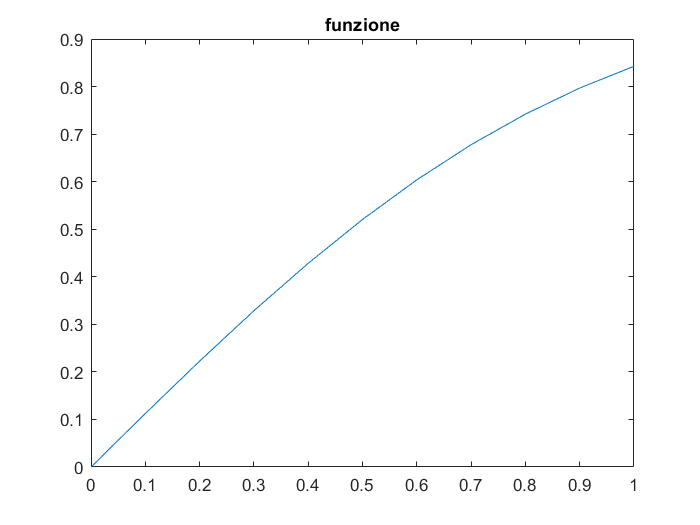

plot(t,y)
title("funzione")

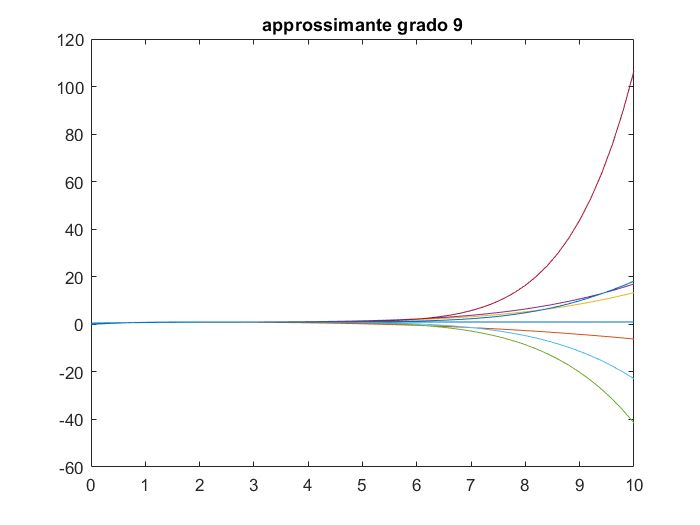

sse=[];
plot(0:0.2:10,erf(0:0.2:10))
hold on
for n=3:9
    [curvefit,gof,output]=fit(t,y,"poly"+n,'Normalize','on');
    title("approssimante grado "+n)
    plot(0:0.2:10,polyval(coeffvalues(curvefit),0:0.2:10))
    sse=[sse gof.sse];
end

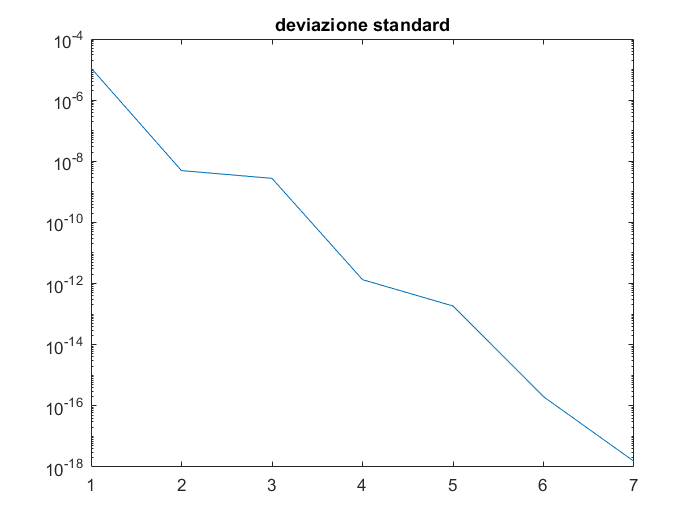

figure()
semilogy(sse)
title("deviazione standard")

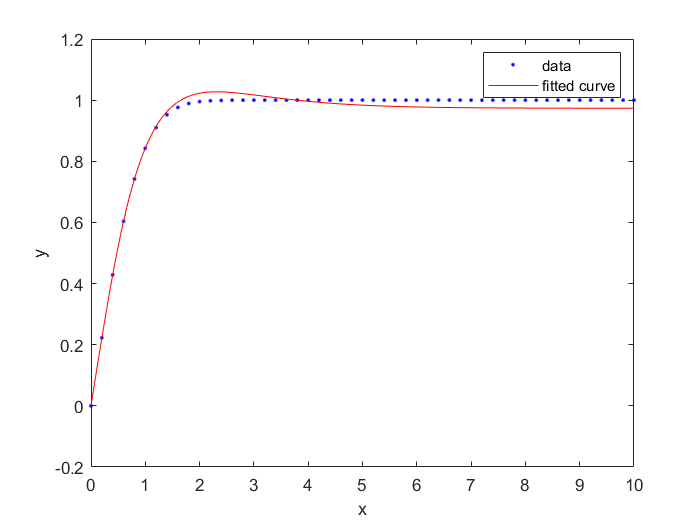

%cftool
load es1_fit_mod.mat
plot(fittedmodel,0:0.2:10,erf(0:0.2:10))

clear all
close all

## Esercizio 2

Il file `winning100.m` contiene nella seconda colonna i tempi ottenuti dai vincitori dei 100 m piani durante le Olimpiadi degli anni dal 1900 al 2016 (riportati nella prima colonna). L'esercizio intende verificare quanto possa essere buona l'approssimazione ottenuta utilizzando i dati per predire il valore successivo delle Olimpiadi di Tokyo 2020/21.

Per caricare i dati usare il comando 

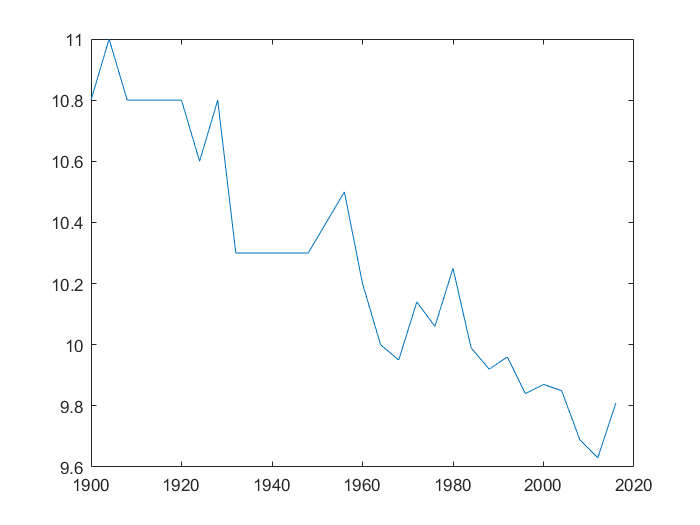

s=load('winning100.m');
x=s(:,1);
y=s(:,2);
plot(x,y)

Eseguire le seguenti operazioni:

- `c`alcolare i polinomi di grado da 1 a 6 che approssimano i dati  nel senso dei minimi quadrati lineari. Calcolare l'errore (scarto quadratico) rispetto ai dati.

- determinare quale polinomio formisce l'approssimazione migliore.

- confrontare i risultati ottenuti con i 6 polinomi approssimanti con il tempo di Marcell Jacobs e commentare il risultato ottenuto.

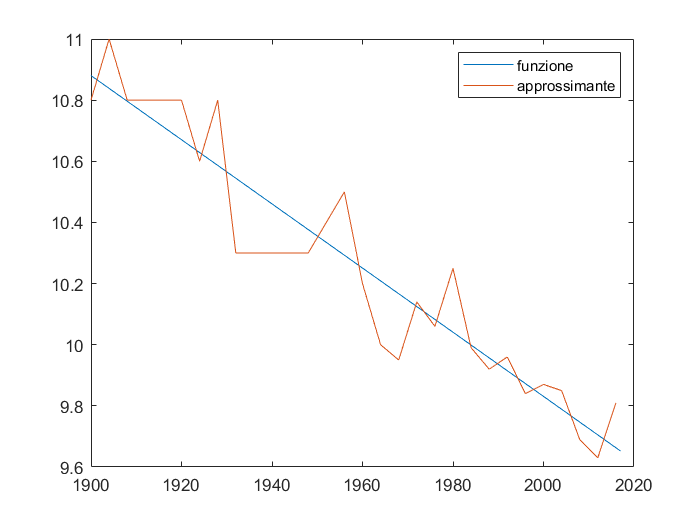

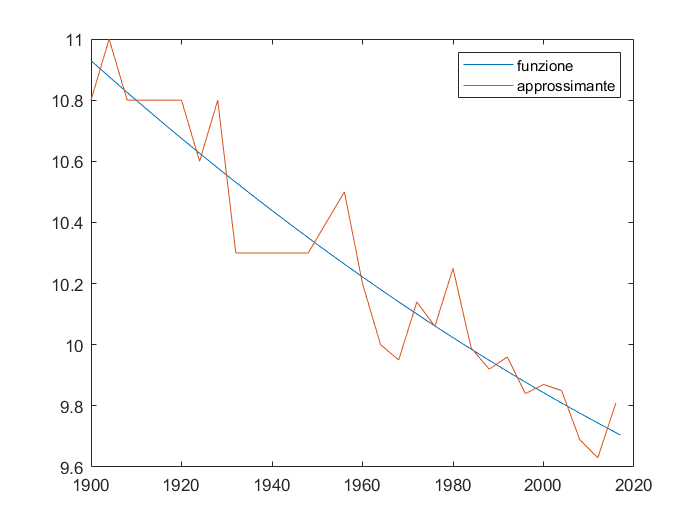

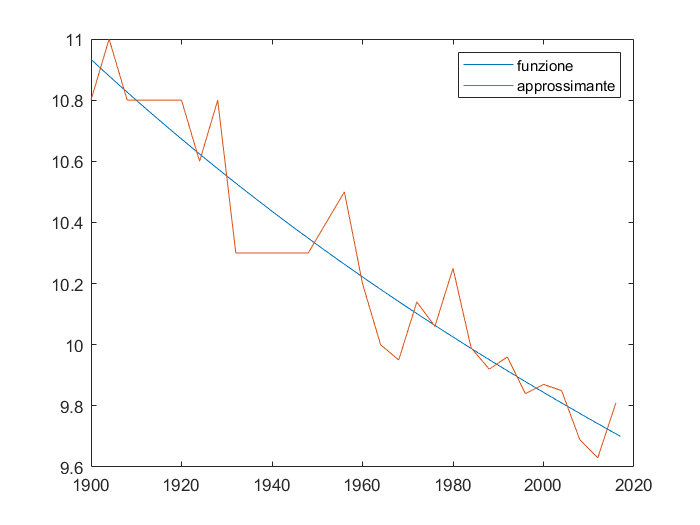

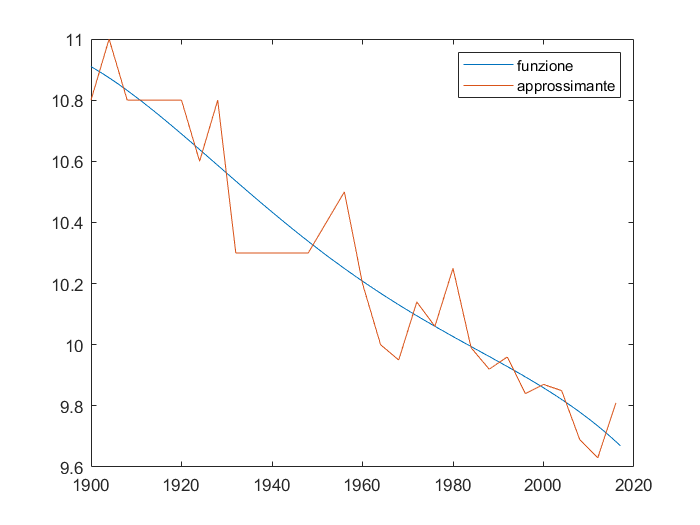

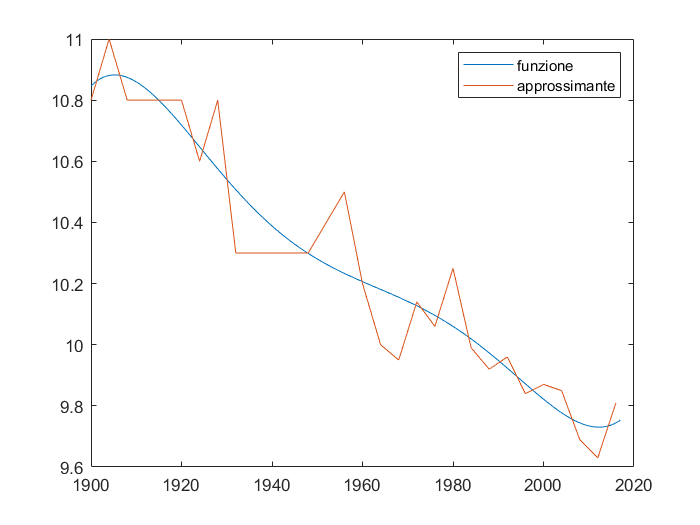

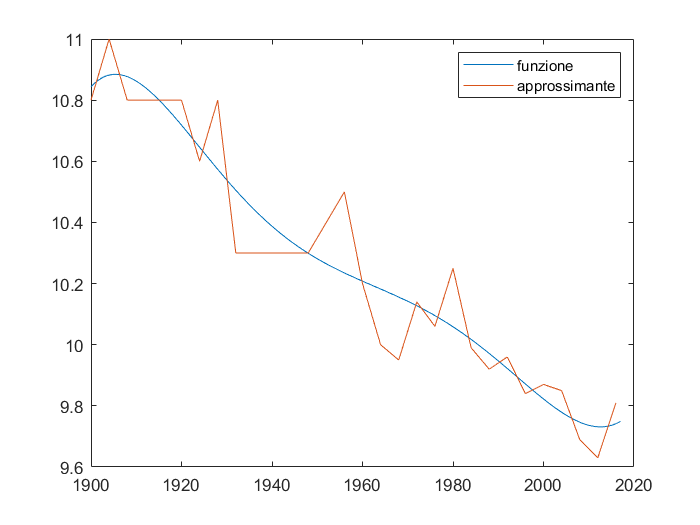

t=[];
rmse=[];
for n=1:6
    figure
    
   
    [curvefit,gof,output]=fit(x,y,"poly"+n);
    rmse=[rmse gof.rmse];
    title("approssimante grado "+n)
    plot(linspace(min(x),max(x)+1,1000),polyval(coeffvalues(curvefit),linspace(min(x),max(x)+1,1000)))
     hold on
    plot(x,y)
    t=[t polyval(coeffvalues(curvefit),2020)];
    legend("funzione","approssimante")
end

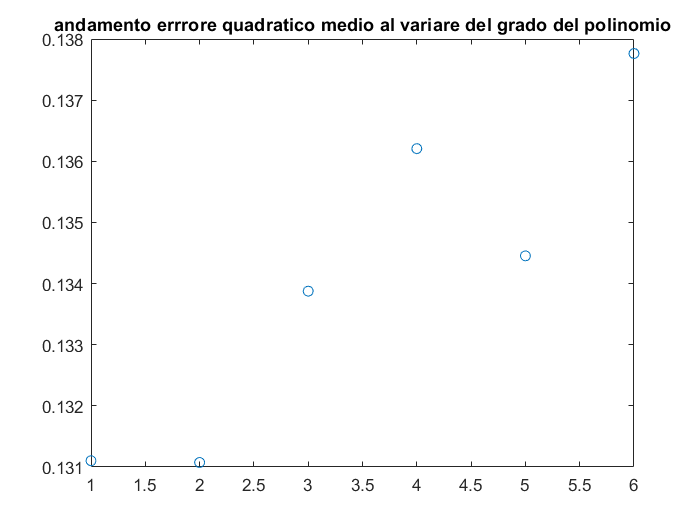

figure 
plot(rmse,"o")
title("andamento errrore quadratico medio al variare del grado del polinomio")

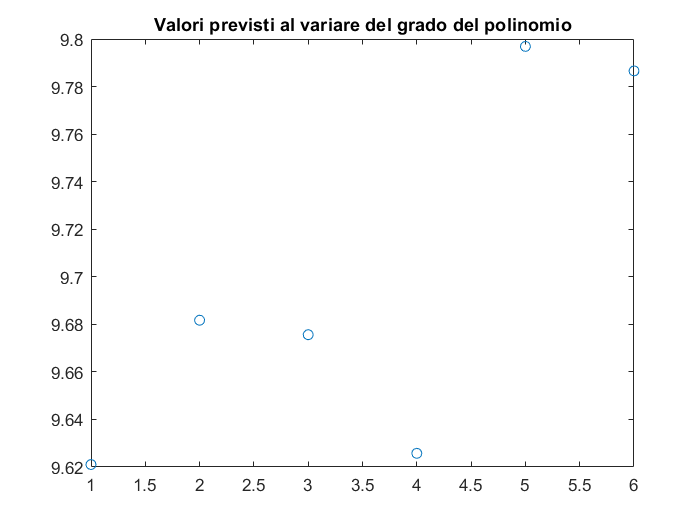

figure
plot(t,"o")
title("Valori previsti al variare del grado del polinomio")